我们考虑如下动态规划问题：


$$V\left(a,s\right)=\max_{a^{\prime } \ge -\phi } \left\lbrace u\left(\left(1+r\right)a-\omega \exp \left(s\right)-a^{\prime } \right)+\beta E\left\lbrack V\left(a^{\prime } ,s^{\prime } \right)|s\right\rbrack \right\rbrace ,s_t =\rho s_{t-1} +\sigma \epsilon_t$$


close all
clear
clc

## 0. 参数设置

global N_a N_s alpha beta delta gamma phi grids_S grids_A ...
    Prob_S a_max L_bar grids_A_fine N_a_fine T
N_a = 300;
N_a_fine = N_a*5;
N_s = 7;
alpha = 0.33;
beta = 0.96;
delta = 0.05;
gamma = 2;
phi = 0;
rho = 0.9;
sigma = 0.1;
a_max = 250;
curv = 0.025;
tol = 1e-6;
maxit = 1000;
crit = 10;
T = 800;
[grids_S, Prob_S] = tauchen(N_s,0,rho,sigma,3);
grids_S = exp(grids_S);
grids_A = grid_power(-phi,a_max,curv,N_a);
invDist_S = ((ones(N_s,1)./N_s)' *Prob_S^10000)';
L_bar = sum(invDist_S .* grids_S);
grids_A_fine = grid_power(-phi,a_max,curv,N_a_fine);
tic
r_sol = fzero(@obj_r,[0.0001,1/beta-1]);
[K_d,K_s,w,V,a_prime,c,mu,M] = solve_price(r_sol);
toc

历时 86.496106 秒。


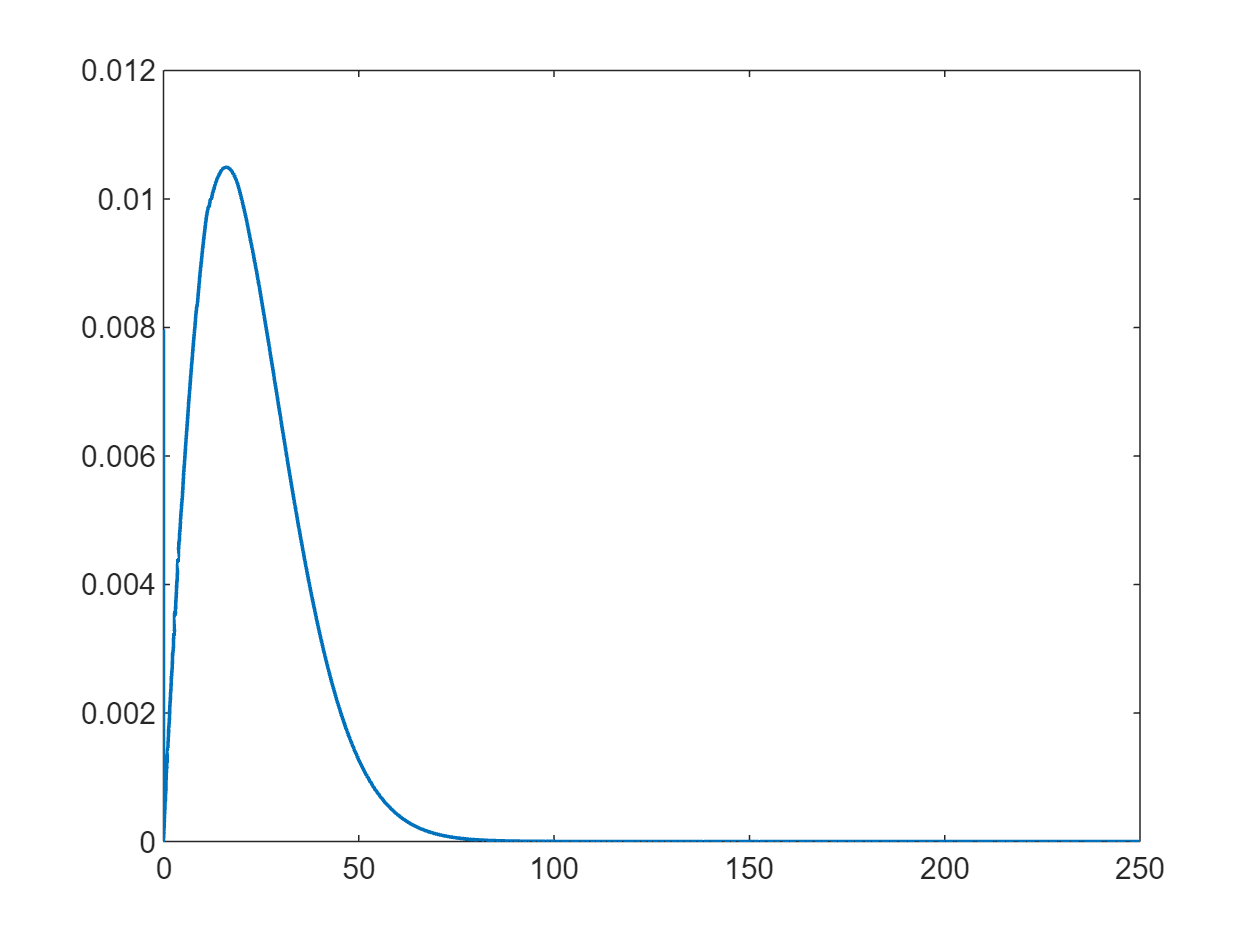

Y = K_d^alpha * L_bar^(1-alpha);
pdf_asset = sum(mu,1);
constrained_HH = pdf_asset(1);

figure
plot(grids_A_fine,pdf_asset,'LineWidth',1.2)

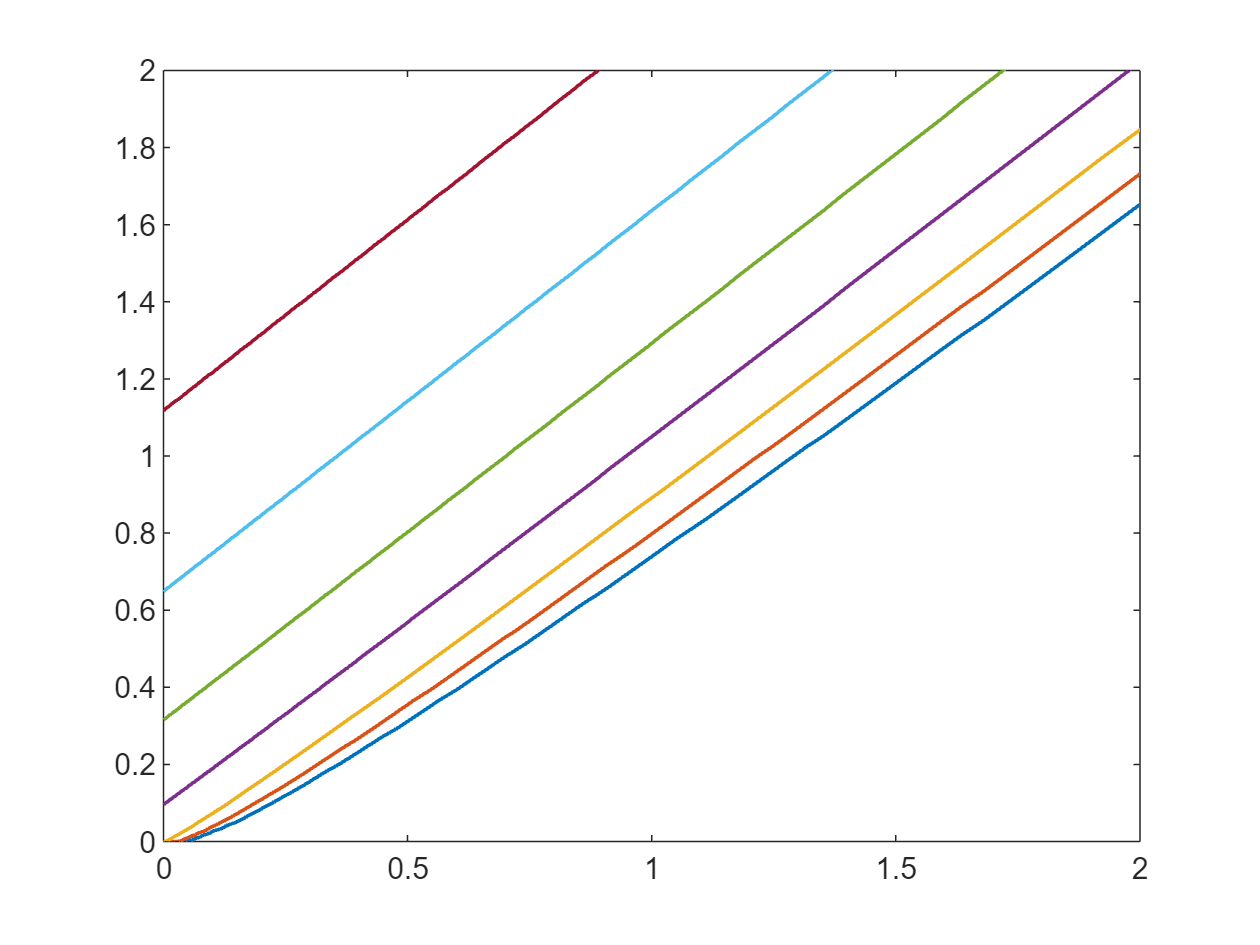

figure
plot(grids_A,a_prime,'LineWidth',1.2)
xlim([0,2])
ylim([0,2])

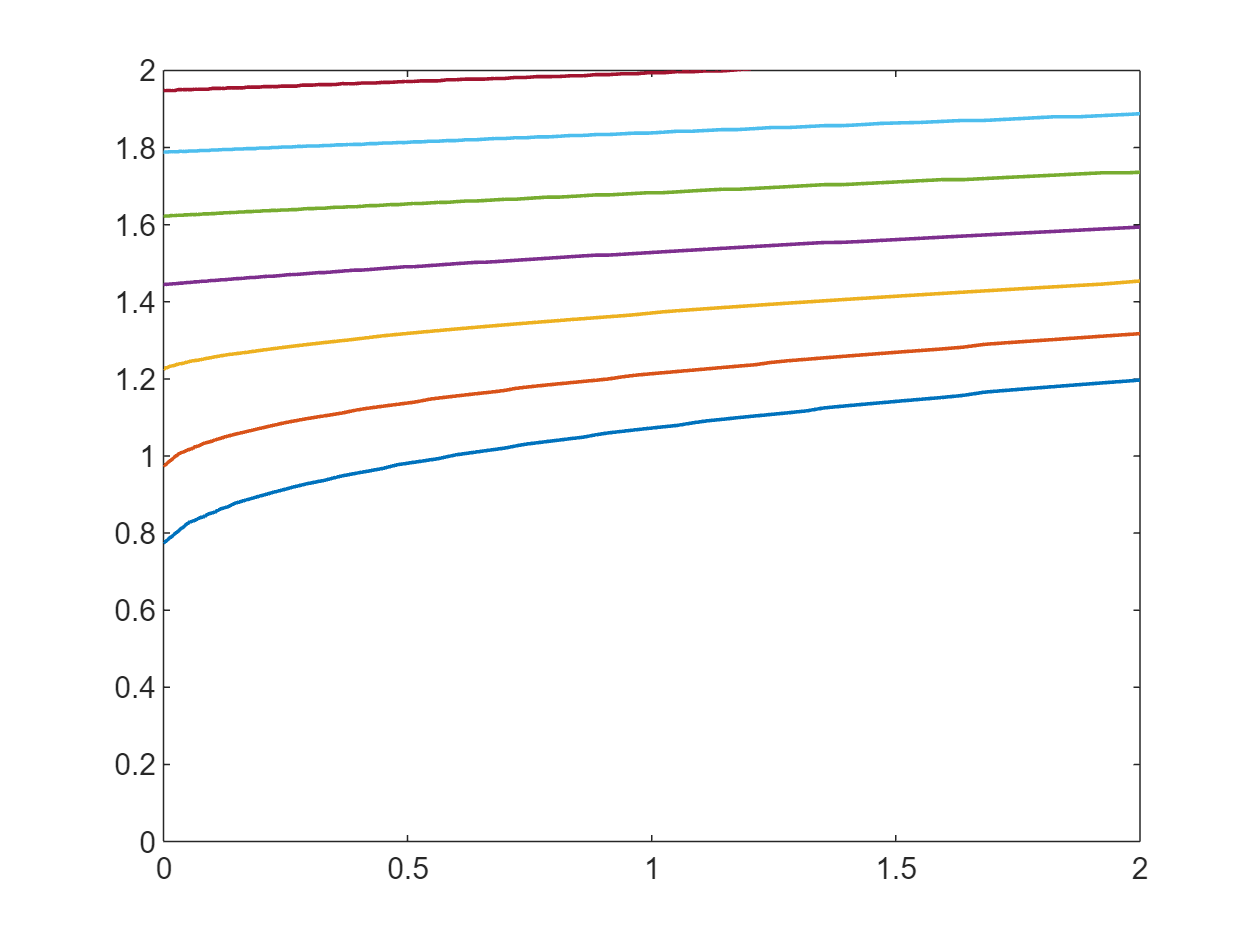

figure
plot(grids_A,c,'LineWidth',1.2)
xlim([0,2])
ylim([0,2])

## SSJ

a_prime_fine = zeros(N_s,N_a_fine);
c_fine = zeros(N_s,N_a_fine);
for i_s = 1:N_s
        a_prime_fine(i_s,:) = interp1(grids_A,a_prime(i_s,:)',grids_A_fine,'linear');
        c_fine(i_s,:) = interp1(grids_A,c(i_s,:)',grids_A_fine,'linear');
end
tic
E = get_E(M,a_prime_fine);
[Y_w,D_w,Y_r,D_r] = get_Y_D(w,r_sol,mu,c_fine);
[J_r,F_r] = build_J(Y_r,D_r,E);
[J_w,F_w] = build_J(Y_w,D_w,E);
toc

历时 25.276147 秒。


## 绘图

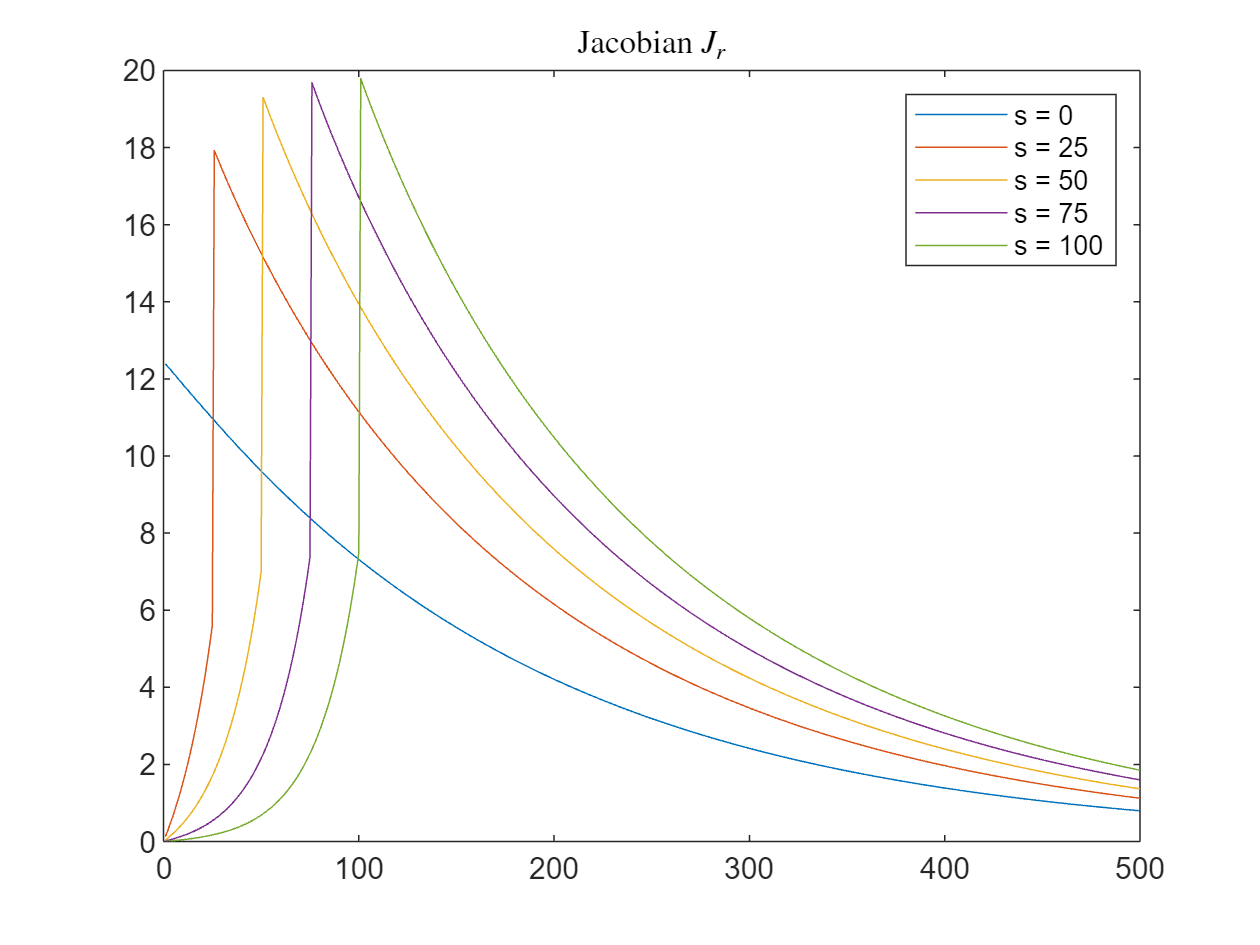

figure
plot(1:T,J_r(:,1+[0,25,50,75,100]))
legend('s = 0', 's = 25','s = 50', 's = 75', 's = 100')
xlim([0,500]);
title('Jacobian $J_r$','Interpreter','latex')

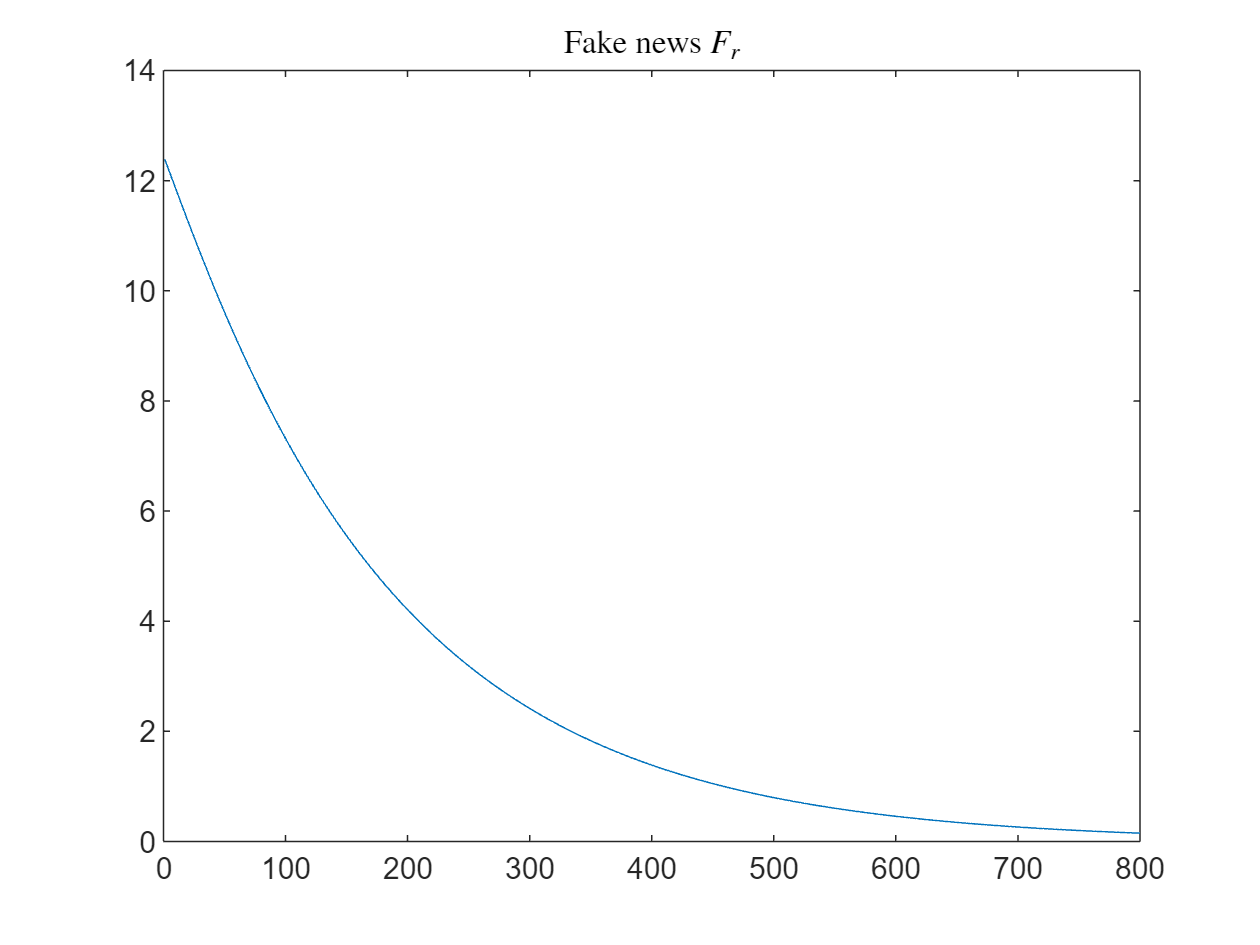

figure
plot(1:T, F_r(:,1))
title('Fake news $F_r$','Interpreter','latex')

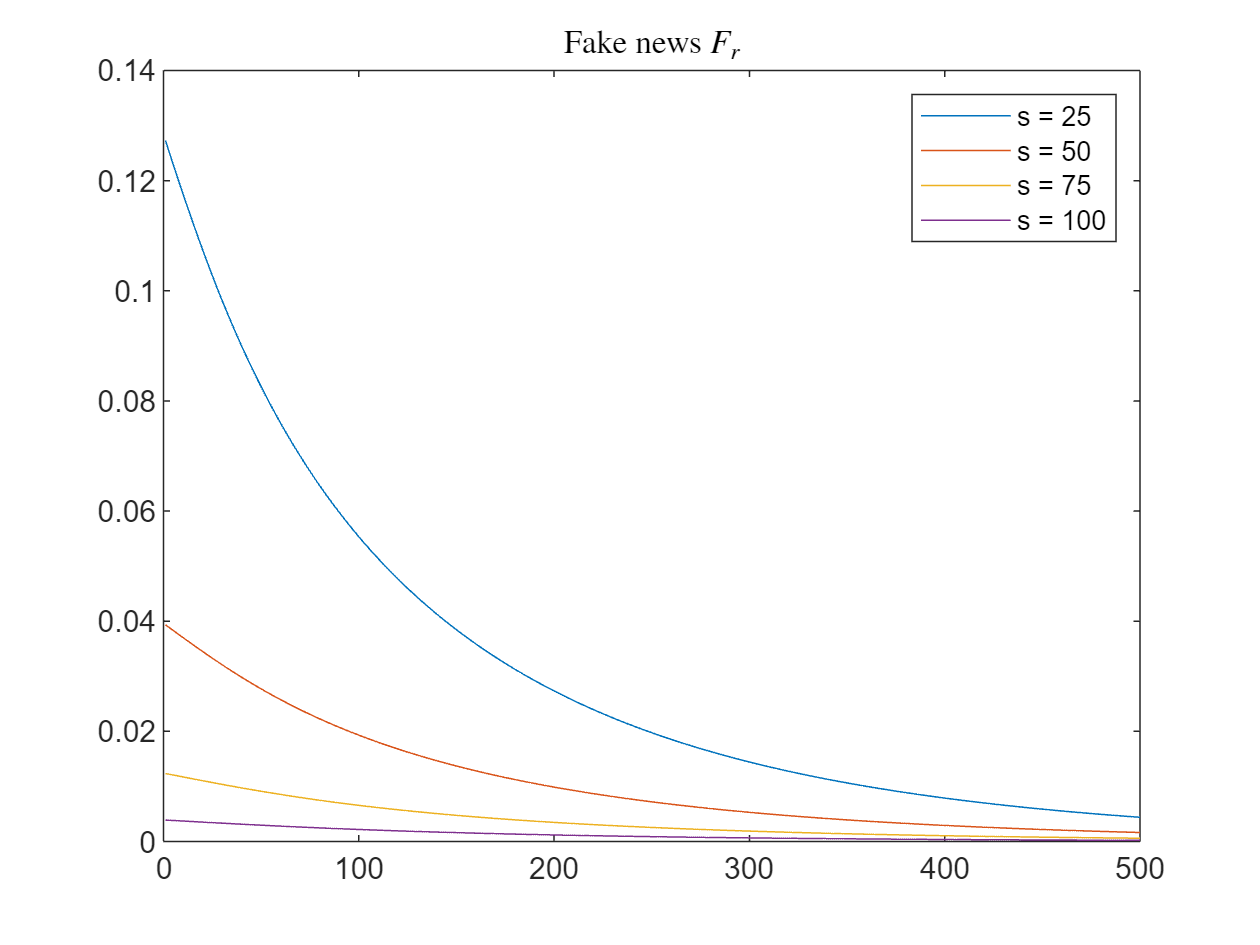

figure
plot(1:T, F_r(:,1+[25,50,75,100]))
legend('s = 25','s = 50', 's = 75', 's = 100')
xlim([0,500]);
title('Fake news  $F_r$','Interpreter','latex')

## 脉冲响应

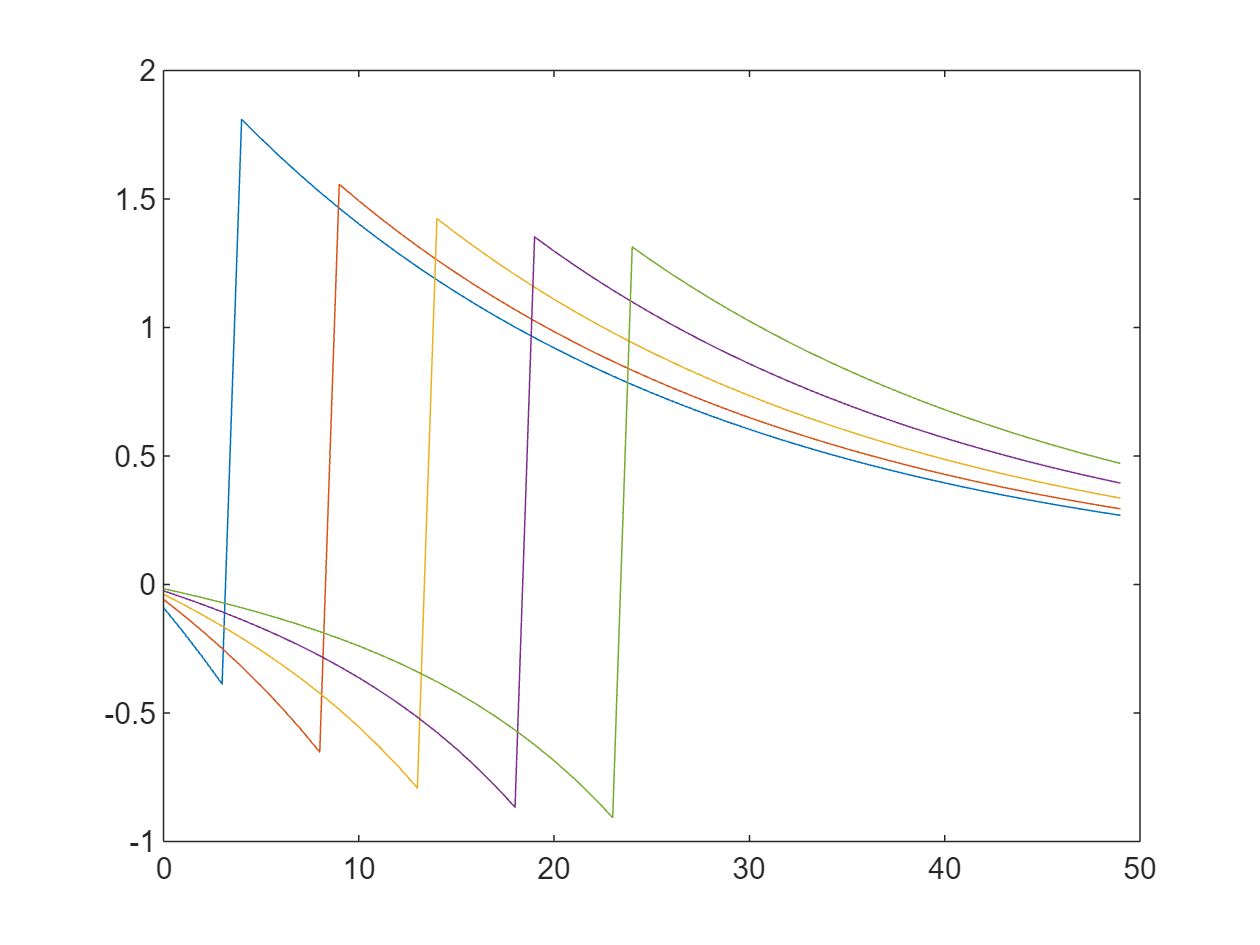

dw_dk = alpha*(1-alpha)*K_s^(alpha-1)*L_bar^(-alpha);
dr_dk = alpha*(alpha-1)*K_s^(alpha-2)*L_bar^(1-alpha);
dw_dz = (1-alpha)*(K_s/L_bar)^(alpha);
dr_dz = (alpha)*(K_s/L_bar)^(alpha-1);
H_k = J_r*dr_dk + J_w*dw_dk - speye(T,T);
H_z = J_r*dr_dz + J_w*dw_dz;
G = -inv(H_k)*H_z;
T_plot = 50;
figure
plot((1:T_plot)-1,G(1:T_plot,[5,10,15,20,25]));

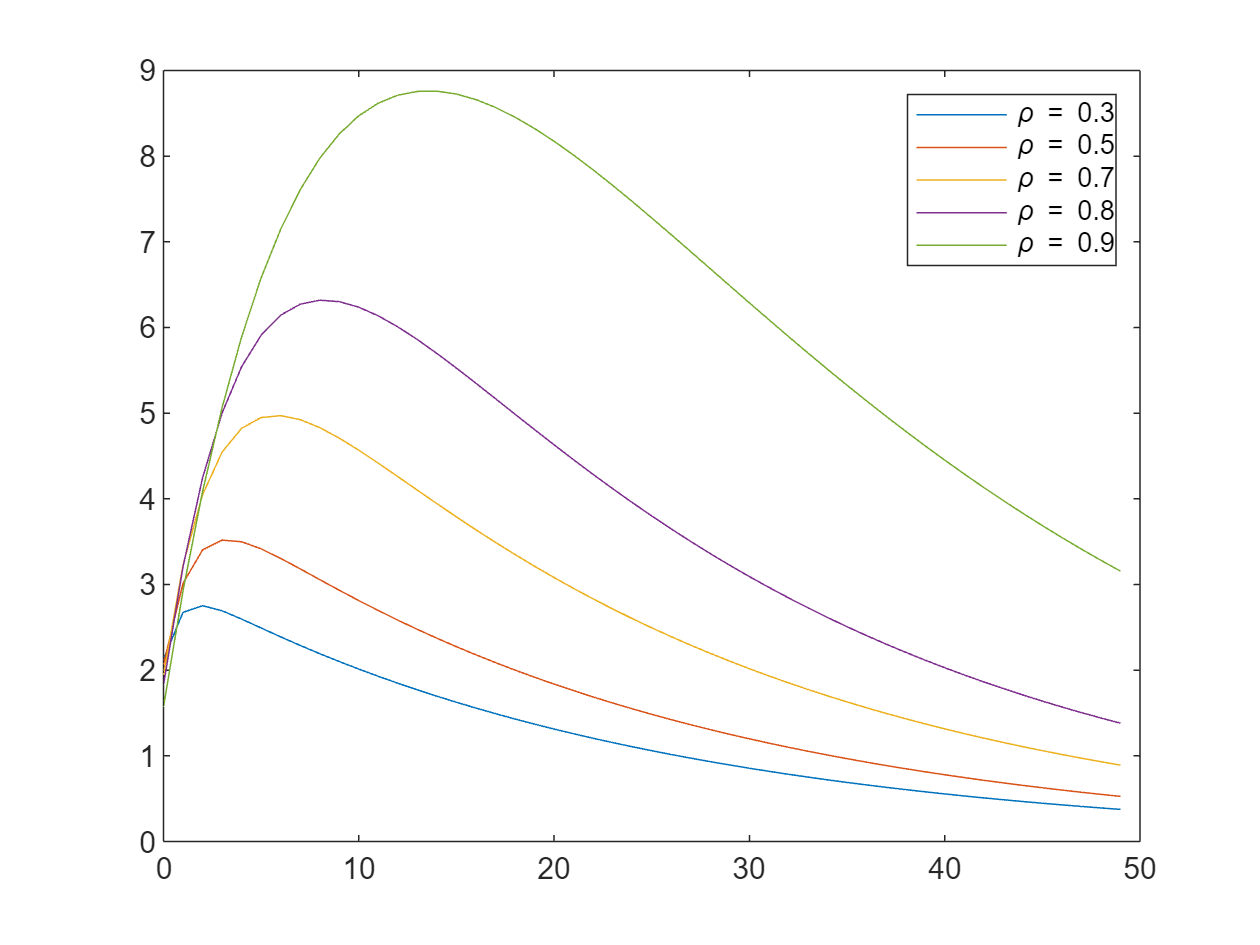

rho_z = [0.3,0.5,0.7,0.8,0.9];
dZs = zeros(T,length(rho_z));
for i_rho = 1:length(rho_z)
    % dZs(:,i_rho) = get_z(0.01,1,rho_z(i_rho),T);
    dZs(:,i_rho) = 0.01.*rho_z(i_rho).^(0:(T-1));
end
tmp = 100*G*dZs;
figure
plot((1:T_plot)-1,tmp(1:T_plot,:))
legend('\rho = 0.3','\rho = 0.5', '\rho = 0.7', '\rho = 0.8', '\rho = 0.9')

## 辅助函数

function [Grids] = grid_power(x_left, x_right, curv, N)
    Grids = x_left + (x_right - x_left)*((1+curv).^((1:1:N)-1)-1)./((1+curv)^(N-1)-1);
    Grids = Grids';
end

function [iweight, ibelow] = coordGridIntp(xtarget, xgrid, robust)
    if nargin < 3
        robust = false;
    end

    xg = length(xgrid);
    iweight = zeros(size(xtarget));
    ibelow = zeros(size(xtarget));

    xi = 1;
    xlow = xgrid(1);
    xhigh = xgrid(2);

    for it = 1:length(xtarget)
        xtval = xtarget(it);

        % 找到区间 [xgrid(xi), xgrid(xi+1)]
        while xi < xg - 1
            if xhigh >= xtval
                break;
            end
            xi = xi + 1;
            xlow = xhigh;
            xhigh = xgrid(xi + 1);
        end

        iweight(it) = (xhigh - xtval) / (xhigh - xlow);
        ibelow(it) = xi;
    end

    if robust
        iweight = min(max(iweight, 0), 1);
        ibelow = min(ibelow, xg - 1);
    end
end

function [V,a_prime,c] = solve_HH(r_init,w_init)
    global N_a N_s alpha beta delta gamma phi grids_S grids_A ...
        Prob_S a_max L_bar grids_A_fine N_a_fine
    tol = 1e-6;
    maxit = 1000;
    crit = 10;
    V = zeros(N_s,N_a);
    a_prime = zeros(N_s,N_a);
    V_new = zeros(N_s,N_a);
    V_old = zeros(N_s,N_a);
    r = r_init;
    w = w_init;
    for iter = 1:maxit
        EV = Prob_S*V;
        for i_s = 1:N_s
            for i_a = 1:N_a
                F = @(ap) ((1+r)*grids_A(i_a)+ w *grids_S(i_s) - ap).^(1-gamma)./(1-gamma) +...
                    beta*interp1(grids_A',EV(i_s,:),ap,"linear");
                obj_F = @(ap)-F(ap);
                a_prime(i_s,i_a) = fminbnd(obj_F,-phi,min(a_max,(1+r)*grids_A(i_a)+...
                    w *grids_S(i_s)-0.000001));
            end
        end
        V_old = V;
        for it = 1:200
            EV_old = Prob_S*V_old;
            for i_s = 1:N_s
                V_new(i_s,:) = ((1+r)*grids_A'+ w *grids_S(i_s) - a_prime(i_s,:)).^(1-gamma)./(1-gamma)+...
                    beta*interp1(grids_A',EV_old(i_s,:),a_prime(i_s,:),"linear");
            end
            crit_inner = max(abs(V_new - V_old),[],'all');
            V_old = V_new;
            if crit_inner < 1e-8
                break
            end
        end
        
        crit = max(abs(V - V_new),[],'all');
        V = V_new;
        if crit < tol
            break
        end
    end
    c = (1+r_init)*grids_A' + w_init*grids_S -a_prime;
end

function [M] = build_M(a_prime,isfine)
  global N_a N_s alpha beta delta gamma phi grids_S grids_A ...
        Prob_S a_max L_bar grids_A_fine N_a_fine
    i_weight = zeros(N_s,N_a_fine);
    i_below = zeros(N_s,N_a_fine);
        for i_s = 1:N_s
            if isfine
                a_prime_fine = interp1(grids_A,a_prime(i_s,:)',grids_A_fine,'linear');
                [i_weight(i_s,:), i_below(i_s,:)] = coordGridIntp(a_prime_fine, grids_A_fine,true);
            else
                [i_weight(i_s,:), i_below(i_s,:)] = coordGridIntp(a_prime(i_s,:)', grids_A_fine,true);
            end
        end
   
 % 利用线性方程组求解平稳分布
    n = N_s * N_a_fine;

    % 每个当前状态最多有 2 * N_s 个下一期去向
    max_nnz = 2 * N_s * N_a_fine * N_s;

    I = zeros(max_nnz, 1);   % 稀疏矩阵的行：下一期状态
    J = zeros(max_nnz, 1);   % 稀疏矩阵的列：当前状态
    V = zeros(max_nnz, 1);   % 对应的转移概率

    q = 0;

    for i_s = 1:N_s
        for i_a = 1:N_a_fine

            % 当前状态 (i_s, i_a) 在 mu(:) 中的位置
            current_idx = i_s + (i_a - 1) * N_s;

            % 资产政策对应的两个相邻资产格点及其权重
            ib = i_below(i_s, i_a);
            wL = i_weight(i_s, i_a);
            wR = 1 - wL;

            % 枚举下一期收入状态
            for i_sp = 1:N_s
                p_s = Prob_S(i_s, i_sp);

                % 去往左侧资产格点 (i_sp, ib)
                q = q + 1;
                I(q) = i_sp + (ib - 1) * N_s;
                J(q) = current_idx;
                V(q) = p_s * wL;

                % 去往右侧资产格点 (i_sp, ib + 1)
                q = q + 1;
                I(q) = i_sp + ib * N_s;
                J(q) = current_idx;
                V(q) = p_s * wR;
            end
        end
    end

    M = sparse(I(1:q), J(1:q), V(1:q), n, n);
end


function [mu,M]=update_dsn(a_prime)
    global N_a N_s alpha beta delta gamma phi grids_S grids_A ...
        Prob_S a_max L_bar grids_A_fine N_a_fine
    M = build_M(a_prime,true);
    n = N_s*N_a_fine;
    % 3. 求 M * mu_vec = mu_vec
    % 固定第一个元素为 1，解其余 n-1 个元素，再正规化
    mu_vec = [1;
        (speye(n - 1) - M(2:end, 2:end)) \ M(2:end, 1)];
    
    % arnold method
    % [mu_vec, ~] = eigs(M, 1);
    % 
    % mu_vec = real(mu_vec);
    % if sum(mu_vec) < 0
    %     mu_vec = -mu_vec;
    % end
    mu_vec = mu_vec / sum(mu_vec);
    
    % 恢复为 N_s x N_a_fine 的二维联合分布
    mu = reshape(mu_vec, N_s, N_a_fine);

    %     mu = ones(N_s,N_a_fine)./(N_s*N_a_fine);
    % 
    % maxit = 10000;
    % for iter = 1:maxit
    %     mu_next = zeros(N_s,N_a_fine);
    %     for i_s = 1:N_s
    %         for i_a = 1:N_a_fine
    %             if mu(i_s,i_a)>0
    %                 mu_next(i_s,i_below(i_s,i_a)) = mu_next(i_s,i_below(i_s,i_a))+mu(i_s,i_a)*i_weight(i_s,i_a);
    %                 mu_next(i_s,i_below(i_s,i_a)+1) = mu_next(i_s,i_below(i_s,i_a)+1)+mu(i_s,i_a)*(1-i_weight(i_s,i_a));
    %             end
    %         end
    %     end
    %     mu_next = (mu_next'*Prob_S)';
    %     crit = max(abs(mu_next - mu),[],'all');
    %     mu = mu_next;
    %     if crit < 1e-12
    %         break
    %     end
    % end
end

function [K_d,K_s,w,V,a_prime,c,mu,M] = solve_price(r_init)
     global N_a N_s alpha beta delta gamma phi grids_S grids_A ...
         Prob_S a_max L_bar grids_A_fine N_a_fine
    K_d = alpha/(r_init+delta)^(1/(1-alpha))*L_bar;
    w = (1-alpha)*(K_d/L_bar)^alpha;
    [V,a_prime,c] = solve_HH(r_init,w);
    [mu,M]=update_dsn(a_prime);
    tmp = sum(mu,1);
    K_s = tmp(:)' *grids_A_fine;

end
function [err] = obj_r(r_init)
    [K_d,K_s,~,~,~,~,~,~] = solve_price(r_init);
    err = K_d - K_s;
end

function [E] = get_E(M,y_ss_fine)
    global T N_a_fine N_s grids_A grids_A_fine
    y_ss_fine = y_ss_fine(:);
    E = zeros(length(y_ss_fine),T+1);
    E(:,1) = y_ss_fine;
    for it = 2:T+1
        E(:,it) = M'*E(:,it-1);
    end
end

function [val] = obj_backward(dx_w,dx_r,w_ss,r_ss,D_ss,c_ss)
    global T N_a_fine N_s grids_A grids_A_fine
    K_path = zeros(1,T);
    D_path = zeros(length(D_ss(:)),T);
    % [~,~,c_temp] = solve_HH(r_ss,w_ss);
    % c_nc = c_temp(1,1);
    % c_rc = c_ss;
    c_next = c_ss;
    for it = T:-1:1
        if it == T
            [a_prime_t, c_t] = backward_iteration(c_next, r_ss+dx_r,w_ss+dx_w, r_ss);
         
        elseif it == T-1
            [a_prime_t, c_t] = backward_iteration(c_next, r_ss,w_ss, r_ss+dx_r);
        else
            [a_prime_t, c_t] = backward_iteration(c_next, r_ss,w_ss, r_ss);
        end
        M = build_M(a_prime_t,false);
        
        % for i_s = 1:N_s
        %     a_prime_fine(i_s,:) = interp1(grids_A,a_prime_t(i_s,:)',grids_A_fine,'linear'); 
        % end
        K_path(it) = (a_prime_t(:))'* D_ss(:);
        D_path(:,it) = M* D_ss(:);
        c_next = c_t;
    end
    K_path = fliplr(K_path);
    D_path = fliplr(D_path);
    val = [K_path(:);D_path(:)];
end

function [a_prime_t, c_t] = backward_iteration( ...
    c_next, r_t, w_t, r_next)

    global N_s N_a_fine beta gamma phi grids_A_fine grids_S Prob_S a_max

    a_grid = grids_A_fine;
    R_t = 1 + r_t;
    R_next = 1 + r_next;
    a_min = -phi;

    a_prime_t = zeros(N_s, N_a_fine);
    c_t = zeros(N_s, N_a_fine);

    % E_t[u'(c_{t+1}) | s_t]
    Emu_next = Prob_S * max(c_next, 1e-12).^(-gamma);

    for i_s = 1:N_s
        % Euler equation:
        % c_t^{-gamma} = beta * (1+r_{t+1}) * E_t[c_{t+1}^{-gamma}]
        c_endo = (beta * R_next * Emu_next(i_s,:)).^(-1/gamma);

        % 给定 a'，反推对应的当期内生资产 a
        a_endo = (c_endo + a_grid' - w_t * grids_S(i_s)) / R_t;

        % 清理可能的重复内生格点，保证 interp1 可用
        [a_endo, keep] = unique(a_endo, 'stable');
        a_prime_endo = a_grid(keep);

        % 从内生资产格点映射回外生资产格点
        ap = interp1( ...
            a_endo, a_prime_endo, a_grid, 'linear', 'extrap')';

        % 借贷约束与资产上界
        constrained = a_grid' <= a_endo(1);
        ap(constrained) = a_min;
        ap = min(max(ap, a_min), a_max);

        a_prime_t(i_s,:) = ap;
        c_t(i_s,:) = R_t * a_grid' + w_t * grids_S(i_s) - ap;
    end
end

function [Y_w, D_w, Y_r, D_r] = get_Y_D(w_ss,r_ss,D_ss,c_ss)
    global T N_a_fine N_s
    f = @(x) obj_backward( ...
        x(1), x(2), ...
        w_ss, r_ss, D_ss, c_ss);
    
    x0 = [0; 0];
    f0 = f(x0);
    
    J = fdjac1(f, x0, f0);
    Y_w = J(1:T,1);
    D_w = J(T+1:end,1);
    D_w = reshape(D_w,N_s*N_a_fine,T);
    Y_r = J(1:T,2);
    D_r = J(T+1:end,2);
    D_r = reshape(D_r,N_s*N_a_fine,T);
end

function [J,F] = build_J(Y,D,E)
    global T
    F = zeros(T,T);
    F(1,:) = Y;
    F(2:end,:) = E(:,1:T-1)'*D;
    J = zeros(T,T);
    J(:,1) = F(:,1);
    J(1,2:end) = F(1,2:end);
    for it = 2:T
        J(2:end,it) = F(2:end,it) + J(1:end-1,it-1);
    end
end

function [dZ, Z_path] = get_z(shock_size,Zss,rho_z,T)
    logz = zeros(T+1,1);
    logz(1) = Zss;
    for it = 2:T+1
        logz(it) = (1+rho_z)*log(Zss)+rho_z*logz(it-1)+ double(it ==2)*shock_size;
    end
    dZ = exp(logz(2:end)) -Zss;
    Z_path = logz(2:end);
end